# Communication systems laboratory Lab4

## [PART1]

### (1)

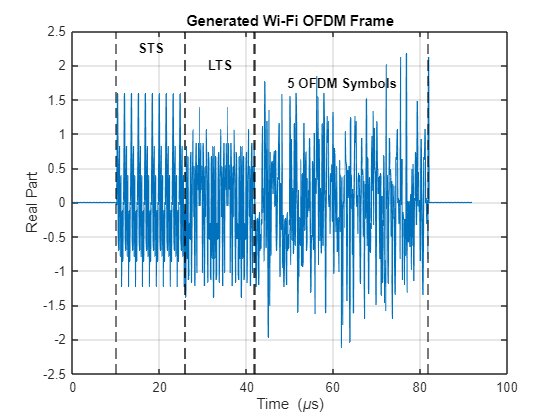

clear all; close all; clc;
FFT_size = 64;
cp_size = 16;
fs = 10e6;
sc_space = fs/FFT_size;
%% 802.11a/g subcarrier allocation
active_sc  = [-26:-1 1:26];           % 52 active subcarriers
pilot_sc = [-21 -7 7 21];           % 4 pilot tones
data_sc  = setdiff(active_sc, pilot_sc); % 48 data tones

% gen_sts
% Usage:
%   sts = gen_sts()
% Input:
%   None
% Output:
%   sts : time-domain 802.11a/g short training sequence, length = 160 samples
function sts = gen_sts()
    FFT_size = 64;

    short_sc = [-24 -20 -16 -12 -8 -4 4 8 12 16 20 24];
    short_val = sqrt(13/6) * ...
        [1+1j; 1+1j; -1-1j; -1-1j; 1+1j; 1+1j; ...
         -1-1j; -1-1j; -1-1j; 1+1j; -1-1j; 1+1j];

    sts_f = zeros(FFT_size, 1);
    sts_f(short_sc + FFT_size/2 + 1) = short_val;

    sts_64 = ifft(ifftshift(sts_f), FFT_size);
    sts_16 = sts_64(1:16);
    sts = repmat(sts_16, 10, 1);
end


% gen_lts
% Usage:
%   lts = gen_lts()
% Input:
%   None
% Output:
%   lts : time-domain 802.11a/g long training sequence, length = 160 samples
%         structure = [32-sample CP; 64-sample LTS; 64-sample LTS]
function lts = gen_lts()
    FFT_size = 64;

    lts_sc = -26:26;
    lts_val = [ ...
         1;  1; -1; -1;  1;  1; -1;  1; -1;  1;  1;  1;  1;  1;  1; -1; ...
        -1;  1;  1; -1;  1; -1;  1;  1;  1;  1; ...
         0; ...
         1; -1; -1;  1;  1; -1;  1; -1;  1; -1; -1; -1; -1; -1;  1;  1; ...
        -1; -1;  1; -1;  1; -1;  1;  1;  1;  1];

    lts_f = zeros(FFT_size, 1);
    lts_f(lts_sc + FFT_size/2 + 1) = lts_val;

    lts_64 = ifft(ifftshift(lts_f), FFT_size);
    lts = [lts_64(end-31:end); lts_64; lts_64];
end


% gen_ofdm_symbol
% Usage:
%   x_cp = gen_ofdm_symbol(data_syms, pilot_syms, data_sc, pilot_sc)
% Input:
%   data_syms  : 48x1 complex vector, data symbols on data subcarriers
%   pilot_syms : 4x1 vector, pilot symbols on pilot subcarriers
%   data_sc    : data subcarrier indices
%   pilot_sc   : pilot subcarrier indices
% Output:
%   x_cp       : one OFDM symbol with cyclic prefix, length = 80 samples
function x_cp = gen_ofdm_symbol(data_syms, pilot_syms, data_sc, pilot_sc)
    FFT_size = 64;
    cp_size = 16;

    X = zeros(FFT_size, 1);
    X(data_sc + FFT_size/2 + 1) = data_syms;
    X(pilot_sc + FFT_size/2 + 1) = pilot_syms;

    x = ifft(ifftshift(X), FFT_size);
    x_cp = [x(end-cp_size+1:end); x];
end


% gen_ofdm_data
% Usage:
%   [ofdm_data, tx_bits, tx_data_syms, pilot_syms] = gen_ofdm_data(num_ofdm_symbols, data_sc, pilot_sc)
% Input:
%   num_ofdm_symbols : number of OFDM symbols to generate
%   data_sc          : data subcarrier indices
%   pilot_sc         : pilot subcarrier indices
% Output:
%   ofdm_data     : concatenated time-domain OFDM symbols with cyclic prefix
%   tx_bits       : transmitted bits on data subcarriers
%   tx_data_syms  : transmitted 4-QAM symbols on data subcarriers
%   pilot_syms    : pilot symbols on pilot subcarriers
function [ofdm_data, tx_bits, tx_data_syms, pilot_syms] = gen_ofdm_data(num_ofdm_symbols, data_sc, pilot_sc)
    FFT_size = 64;
    cp_size = 16;

    num_data = length(data_sc);
    num_pilot = length(pilot_sc);

    tx_bits = randi([0 1], 2*num_data, num_ofdm_symbols);
    tx_data_syms = zeros(num_data, num_ofdm_symbols);
    pilot_syms = ones(num_pilot, num_ofdm_symbols);

    ofdm_data = zeros((FFT_size + cp_size) * num_ofdm_symbols, 1);

    for sym_idx = 1:num_ofdm_symbols
        data_syms = qammod(tx_bits(:, sym_idx), 4, ...
            'InputType', 'bit', 'UnitAveragePower', true);

        tx_data_syms(:, sym_idx) = data_syms;

        X = zeros(FFT_size, 1);
        X(data_sc + FFT_size/2 + 1) = data_syms;
        X(pilot_sc + FFT_size/2 + 1) = pilot_syms(:, sym_idx);

        x = ifft(ifftshift(X), FFT_size);
        x_cp = [x(end-cp_size+1:end); x];

        start_idx = (sym_idx - 1) * (FFT_size + cp_size) + 1;
        end_idx = sym_idx * (FFT_size + cp_size);
        ofdm_data(start_idx:end_idx) = x_cp;
    end
end


% plot_td_signal
% Usage:
%   plot_td_signal(x, fs, fig_title, plot_mode, region_names, region_ranges)
% Input:
%   x             : input signal in time domain
%   fs            : sampling rate in Hz
%   fig_title     : figure title
%   plot_mode     : 'Real', 'Imag', or 'Abs'
%   region_names  : 1xN cell array, label names of marked regions
%   region_ranges : Nx2 matrix, each row = [start_idx end_idx]
% Output:
%   None
%   This function plots a time-domain signal in microseconds and optionally
%   marks specified regions with vertical boundaries and labels
function plot_td_signal(x, fs, fig_title, plot_mode, region_names, region_ranges)
    t_us = (0:length(x)-1).' / fs * 1e6;

    switch lower(plot_mode)
        case 'real'
            y = real(x);
            y_label = 'Real Part';
        case 'imag'
            y = imag(x);
            y_label = 'Imaginary Part';
        case 'abs'
            y = abs(x);
            y_label = 'Magnitude';
        otherwise
            error('plot_mode must be ''Real'', ''Imag'', or ''Abs''.');
    end

    figure;
    plot(t_us, y, 'LineWidth', 1);
    grid on;
    xlabel('Time (\mus)');
    ylabel(y_label);
    title(fig_title);
    hold on;

    if nargin < 5 || isempty(region_names) || isempty(region_ranges)
        return;
    end

    yl = ylim;

    for k = 1:size(region_ranges, 1)
        idx_start = region_ranges(k, 1);
        idx_end = region_ranges(k, 2);

        xline(t_us(idx_start), '--k');
        xline(t_us(idx_end), '--k');

        text(mean(t_us(idx_start:idx_end)), yl(2) * (0.9 - 0.1*(k-1)), region_names{k}, ...
            'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

num_ofdm_symbols = 5;
pad_len = 100;

%% (1) Generate a frame with STS, LTS, and 5 OFDM symbols
sts = gen_sts();
lts = gen_lts();
[ofdm_data, tx_bits, tx_data_syms, pilot_syms] = gen_ofdm_data(num_ofdm_symbols, data_sc, pilot_sc);

sts = sts / rms(sts);
lts = lts / rms(lts);
ofdm_data = ofdm_data / rms(ofdm_data);

tx_frame = [zeros(pad_len,1); sts; lts; ofdm_data; zeros(pad_len,1)];

region_names = {'STS', 'LTS', '5 OFDM Symbols'};
region_ranges = [
    pad_len + 1,                              pad_len + length(sts);
    pad_len + length(sts) + 1,                pad_len + length(sts) + length(lts);
    pad_len + length(sts) + length(lts) + 1,  pad_len + length(sts) + length(lts) + length(ofdm_data)
];

plot_td_signal(tx_frame, fs, 'Generated Wi-Fi OFDM Frame', 'Real', region_names, region_ranges);

### (2)

fc = 885e6;
tx_gain = 5;
rx_gain = 5;

% setup_usrp
% Usage:
%   [tx_usrp, rx_usrp] = setup_usrp(fc, fs, tx_gain, rx_gain)
% Input:
%   fc      : carrier frequency in Hz
%   fs      : sampling rate in Hz
%   tx_gain : transmit gain in dB
%   rx_gain : receive gain in dB
% Output:
%   tx_usrp : configured USRP transmitter object
%   rx_usrp : configured USRP receiver object
function [tx_usrp, rx_usrp] = USRP_init(fc, tx_gain, rx_gain, rx_length)
    % master_clock_rate = 100e6;
    % interp_decim = master_clock_rate / fs;

    tx_usrp = comm.SDRuTransmitter( ...
        'Platform',            'N200/N210/USRP2', ...
        'IPAddress',           '192.168.10.2', ...
        'CenterFrequency',     fc, ...
        'InterpolationFactor',  10, ...
        'Gain',                tx_gain);

    rx_usrp = comm.SDRuReceiver( ...
        'Platform',            'N200/N210/USRP2', ...
        'IPAddress',           '192.168.10.2', ...
        'CenterFrequency',     fc, ...
        'Gain',                rx_gain, ...
        'SamplesPerFrame',     rx_length, ...
        'DecimationFactor',    10, ...
        'OutputDataType',      'double');
end

% % Use the frame generated in (1)
data = tx_frame;

% To ensure capturing a whole frame, receive longer than the transmitted frame
rx_length = 200 * (length(tx_frame) + 500);

% Check USRP connection
info = findsdru();

Checking radio connections...


while info.Status ~= "Success"
    release(radio_Tx);
    release(radio_Rx);
    pause(1);
    info = findsdru();
end

% Initialize USRP
[radio_Tx, radio_Rx] = USRP_init(fc, tx_gain, rx_gain, rx_length);

% Matched filter for STS detection
match_filter = conj(flipud(sts));

% Variables for repeated transmission
buffer = zeros(rx_length, 1);
tunderrun = 0;
toverflow = 0;
maxattempts = 50;
success = 0;
threshold = 1;
start_point = 0;

for attempt = 1:maxattempts

    % Transmit the generated frame
    tunderrun = radio_Tx(data);

    % Receive signal
    [received_signal, ~, toverflow] = step(radio_Rx);

    % STS matched filter
    corr = abs(conv(received_signal, match_filter));
    maxval = max(corr);

    if maxval >= threshold

        % Store received signal
        buffer(:,1) = received_signal;

        % Find the approximate STS position
        [~, peak_idx] = max(corr);

        % Since the matched filter peak appears near the matched segment,
        % estimate the STS start point from the peak position
        sts_start = peak_idx - 160 + 1;

        % The transmitted frame has 100 zeros before STS
        frame_start = sts_start - pad_len;

        if frame_start < 1
            frame_start = 1;
        end

        frame_end = frame_start + length(tx_frame) - 1;

        if frame_end > length(buffer)
            frame_end = length(buffer);
        end

        start_point = frame_start;
        success = 1;
        break

    else
        fprintf("Attempt %d: max corr = %.6f\n", attempt, maxval);
    end
end

Attempt 1: max corr = 0.008768
Attempt 2: max corr = 0.008741
Attempt 3: max corr = 0.006805
Attempt 4: max corr = 0.007582
Attempt 5: max corr = 0.010008
Attempt 6: max corr = 0.008490
Attempt 7: max corr = 0.008263
Attempt 8: max corr = 0.008930
Attempt 9: max corr = 0.008538
Attempt 10: max corr = 0.007956
Attempt 11: max corr = 0.014440
Attempt 12: max corr = 0.008098
Attempt 13: max corr = 0.007315
Attempt 14: max corr = 0.008440
Attempt 15: max corr = 0.008053
Attempt 16: max corr = 0.009391


if success
    disp("SUCCESS!");
else
    release(radio_Tx);
    release(radio_Rx);
    error("FAIL! No valid frame detected.");
end

SUCCESS!


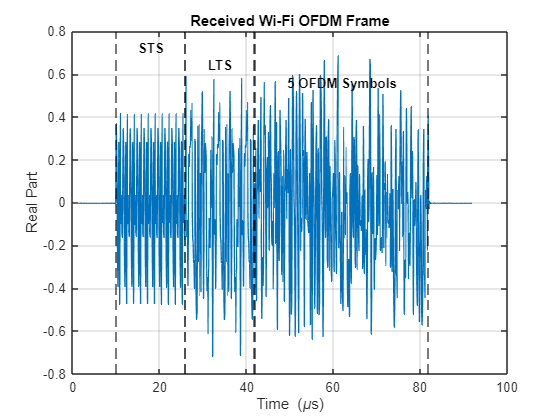

% Extract received frame
rx_frame = buffer(start_point:frame_end);

% Release USRP resources
release(radio_Tx);
release(radio_Rx);

% Mark STS, LTS, and OFDM data symbols
rx_region_names = {'STS', 'LTS', '5 OFDM Symbols'};

rx_region_ranges = [
    pad_len + 1,                              pad_len + length(sts);
    pad_len + length(sts) + 1,                pad_len + length(sts) + length(lts);
    pad_len + length(sts) + length(lts) + 1,  pad_len + length(sts) + length(lts) + length(ofdm_data)
];

% Plot received frame in time domain
plot_td_signal(rx_frame, fs, 'Received Wi-Fi OFDM Frame', 'Real', rx_region_names, rx_region_ranges);

### (3)

We ensure the OFDM sample rate is 10 MHz by setting the USRP master clock rate to 100 MHz and configuring both the interpolation factor and decimation factor to 10. Therefore, the transmit baseband sample rate is 100M/10 = 10 MHz, and the receive baseband sample rate is also 100M/10 = 10 MHz. In the transmit chain, interpolation is applied before the DAC to raise the baseband sampling rate to the internal USRP clock rate. In the receive chain, decimation is applied after the ADC to reduce the internal sampling rate back to the desired baseband rate. Hence, both transmission and reception operate at the required OFDM sample rate of 10 MHz. 

### (4)

mf  = conj(flipud(sts));

mf_result = abs(conv(rx_frame, mf));

[~, sts_end] = max(mf_result);

fprintf("Beginning of first long training symbol = %d\n", sts_end + 33);

Beginning of first long training symbol = 293


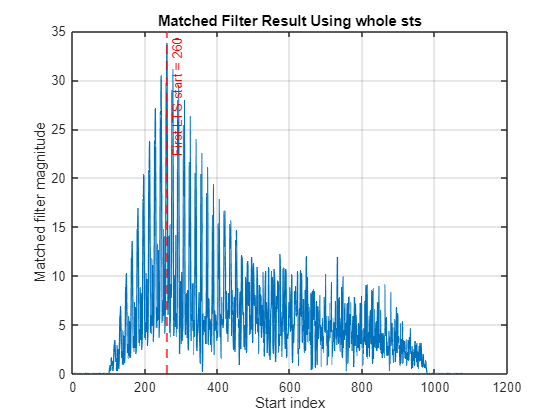

figure;
plot(1:length(mf_result), mf_result, 'LineWidth', 1);
grid on;
xlabel('Start index');
ylabel('Matched filter magnitude');
title('Matched Filter Result Using whole sts');

hold on;
xline(sts_end, '--r', sprintf('First LTS start = %d', sts_end), 'LineWidth', 1.5);